# Coffee

Add a local function called **rate_func** that takes **t** and **y** and computes **dy/dt**.  In this case, rate_func does not actually depend on `t` ; nevertheless, your function has to take `t`  as the first input variable in order to interface with the `ode45` algorithm.

function dydt = rate_func(t, y)
    k = 0.01;  % deg/min
    e = 20;    % C
    dydt = -k*(y-e);
end

Test your function by adding a line like `rate_func(0, 90)` to call the local function and confirm that the initial rate is -0.7 °C/min.

rate_func(0, 90)

ans = -0.7000

Once you get `rate_func`  working, modify live script to use `ode45`  to compute the temperature of the coffee for 60 minutes.  Confirm that the coffee cools quickly at first, then cools more slowly, and reaches room temperature after about an hour.

% Initial conditions
y0 = 90;
tspan = [0 100];
[tt, yy] = ode45(@rate_func, tspan, y0);

Plot the results and estimate the time when the temperature reaches 50 °C .  Add appropriate labels (with units) to the plot.

figure;
clf;
plot(tt,yy)
xlabel("Time (hrs)")
ylabel("Coffee temp. (C)")
grid('on')


Based on the numerical results from the ODE solution, when when the temperature reaches 50 °C? Report the time and temperature when the temperature is first at or less than 50 °C as a formatted string.

indx = find(yy <= 50);
time_to_50 = yy(indx(1))

time_to_50 = 49.9190

fprintf("At time %.2f hr the temperature is %.1f C.", tt(indx(1)), yy(indx(1)))

At time 85.00 hr the temperature is 49.9 C.

Optionally, annotate the plot

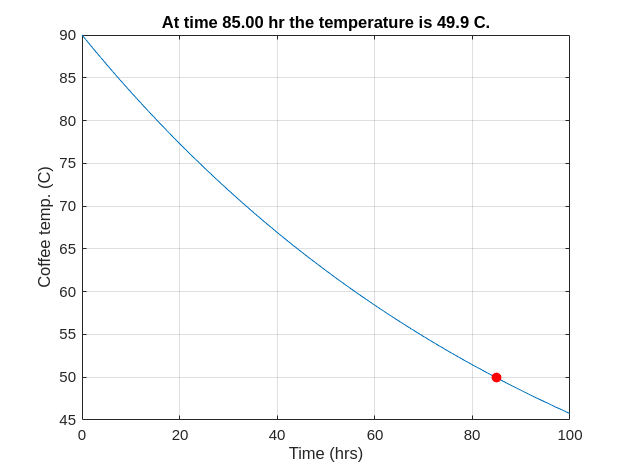

hold on
plot(tt(indx(1)), yy(indx(1)), 'ro','MarkerFaceColor','r')
title(sprintf("At time %.2f hr the temperature is %.1f C.", tt(indx(1)), yy(indx(1))))